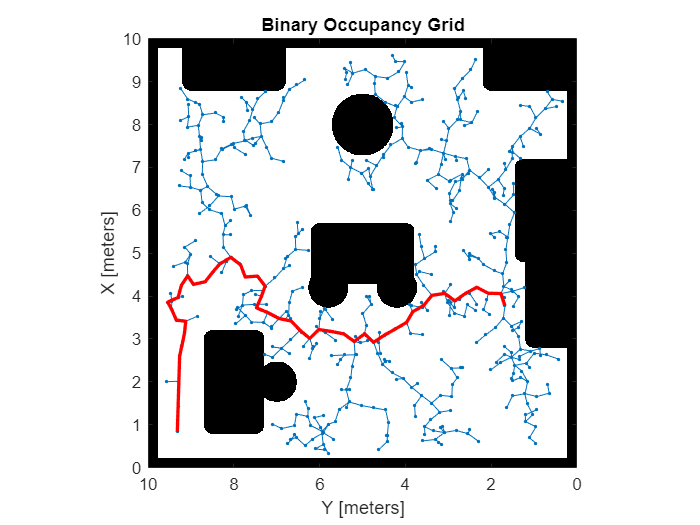

if ~exist('binary_map','var')
    define_binary_map;
end

p_start = rand_pt_in_map(binary_map_inflated);
p_end = rand_pt_in_map(binary_map_inflated);
pts = [p_start; p_end];

ss = stateSpaceSE2;
sv = validatorOccupancyMap(ss);
sv.Map = binary_map_inflated;
sv.ValidationDistance = 0.01;
ss.StateBounds = [binary_map_inflated.XWorldLimits;binary_map_inflated.YWorldLimits; [-pi pi]];
planner = plannerRRT(ss,sv);
planner.MaxConnectionDistance = 0.3;

[pthObj,solnInfo] = plan(planner,[p_start 0],[p_end 0]);

show(binary_map_inflated)
hold on
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-'); % tree expansion
plot(pthObj.States(:,1),pthObj.States(:,2),'r-','LineWidth',2) % draw path
hold off
view(-90,90);